# Load Data, Sampling Rate=1sample/1seg

clear;clc;%clear all
%Prepare the raw dataset
%load('./data/dataset_raw.mat');%Load table data
%data(:,19)=[];%delete empty data
%data(:,13:17)=[];%delete empty data
%data(:,1)=[];%delete the topics
load('./data/dataset.mat');%Load table data
dataNew=table2array(data(:,4:12));% Array Double

# Plot Data

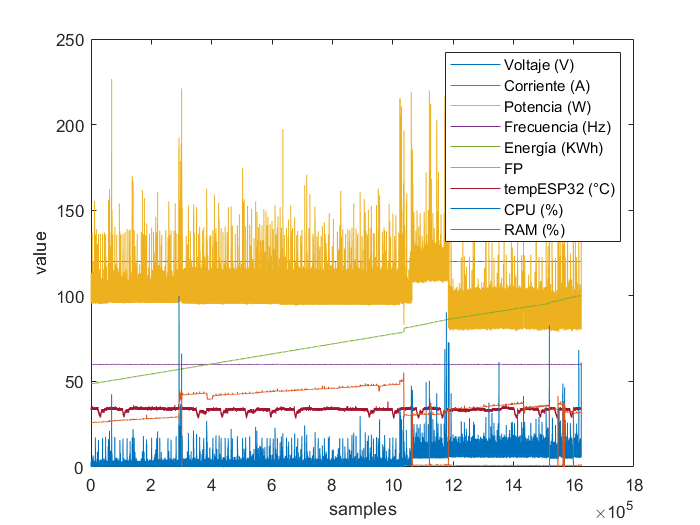

figure
plot(dataNew);xlabel('samples');ylabel('value');
legend('Voltaje (V)','Corriente (A)','Potencia (W)','Frecuencia (Hz)','Energía (KWh)','FP','tempESP32 (°C)','CPU (%)','RAM (%)');

Input output Data

training=0.7;
testing=0.3;
TimeStep =86400;% en Segundos (2592000=1 mes,604800=1 semana,86400=1 día, 3600=1 hora, 60=1 min)
% inputs: 'Voltaje','Corriente','Potencia','Frecuencia','Energía','FP','tempESP32'
input=dataNew(1:round(length(dataNew)*training)-TimeStep,:);
% output: Energía in the following time step
output=dataNew(1+TimeStep:round(length(dataNew)*training),5);